# AC_Voltammetry

%clc;
%clear;
%close all;

% Data is collected as a sound file (.data). After uploading the file in
% this script, first enter the frequency used during the measurements. The
% uncertainty frequency (� window) is defined next (sec_hr_bw).

% ------------------------------Data Analysis-----------------------------%

y = load('10ppm.data');       % File name in .data format
%testy = load('../atesty.txt');
%testi = load('../atesti.txt');
%testc = load('../atestc.txt');

freq_pert = 60;                % Frequency perturbation
sec_har_bw = 10;                % Band-width window
lpf_bw = 10;                    % env lpf bandwidth
har_num = 2;                    % harmonic to use (normally 2)

blank_samples = 4000;          % set first samples to zero

max_time = 1.5;                % Maximum time
max_width = 0.2;

sample_rate = 8000.0;          % sample rate

max_index_l = round((max_time - max_width) * sample_rate);
max_index_u = round((max_time + max_width) * sample_rate);

a = size(y);                   % Sample size
nod = a(1);                    % Number of data points

dt = 1/sample_rate;            % Distance between the data points
df = sample_rate/nod;          % Sample rate

n = 1:nod;                     % Creating a column vector with


t = n*dt;
f = n*df;

v = y(:,1);                    % Column 1: Voltage
i = y(:,2);                    % Column 2: Current

v(1:blank_samples) = 0;          % blank voltage
i(1:blank_samples) = 0;          % blank current

Imag = ((abs(fft(i)/nod*2)));  % Magnitude of Current (Abselute value of fourier transform

%FFT filtering
% frequency domain
p = fft(i);
%sample position of freq_pert x 2
sample_freq_pert = freq_pert*2/sample_rate*nod;
%sample number of lpf_bw
sample_lpf_bw = sec_har_bw/sample_rate*nod;
%blanking of fft date
p_filtered = p;
p_filtered(1:(sample_freq_pert-sample_lpf_bw/2))=0.0;
p_filtered((sample_freq_pert+sample_lpf_bw/2):(nod-sample_freq_pert-sample_lpf_bw/2))=0.0;
p_filtered((nod-sample_freq_pert+sample_lpf_bw/2):nod)=0.0;
% time domain waveform
p_wave = real(ifft(p_filtered));

% Filter size

n = 2046;

% Display range

d1 = 001;
d2 = 10001;

% Low pass cut off

fc = freq_pert*har_num;
bw = sec_har_bw;

% Full ADC rate

fs2 = sample_rate/2;

ff = [0 (fc-bw)/fs2*0.99 (fc-bw)/fs2 (fc+bw)/fs2 (fc+bw)/fs2*1.01 1]; m = [0 0 1 1 0 0];
b = fir2(n,ff,m);
c = b./max(b);
[h,~] = freqz(c,1,100001);

gain = (max(abs(h)));
c = c/gain;
        fid = fopen('newcvalues.txt','w');
        fprintf(fid,'%f\n',c);
        fclose(fid);

ifilt = filter(c,1,i);
Imagfilt = ((abs(fft(ifilt)/nod*2)));


%plot(y);

i2sin = sin(2*pi*fc.*t)';
i2cosin = cos(2*pi*fc.*t)';

ixsin = ifilt .* i2sin;
ixcosin = ifilt .* i2cosin;

fc2 = lpf_bw;
ff = [0 fc2/fs2 fc2/fs2*1.01 1]; m = [0 0 1 1];
b = fir2(n,ff,m);
c = b./max(b);
[h,w] = freqz(c,1,100001);

gain = (max(abs(h)));
c = c/gain;

ixsin_filt = filter(c,1,ixsin);
ixcosin_filt = filter(c,1,ixcosin);

ienv = 2*sqrt(ixsin_filt .* ixsin_filt + ixcosin_filt .* ixcosin_filt);
int_ienv = cumsum(ienv);

% vfilt = filter(c,1,v);

disp(max(ienv(max_index_l:max_index_u)))

  157.6115



disp(max(ienv(max_index_l:max_index_u)) / max(ienv(round(nod*0.1):round(nod*0.9))) * 100);

   15.6646




doff = 1;

## Filter ienv (filtfilt = Zero-phase digital filtering)

filter_length = 200;
ienv_filtered = ienv(doff:nod-doff);
ienv_filtered = filtfilt(ones(filter_length,1)/filter_length,1,ienv_filtered);

## Firgure 1: Plot of Current (S.U) vs. Time (S)

It is obtained after applying the filter to extract the 2nd Harmonic FT of the signal.

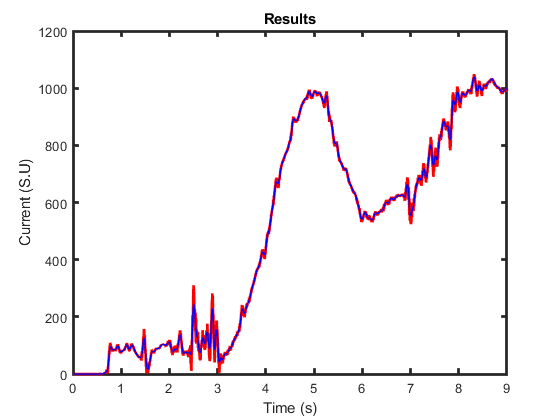

figure
plot(t(doff:nod-doff),ienv(doff:nod-doff),'-r','linewidth',2);
hold on
plot(t(doff:nod-doff),ienv_filtered,'b','linewidth',1);
xlabel('Time (s)');
ylabel('Current (S.U)');
title('Results');
set(gca,'linewidth',2);

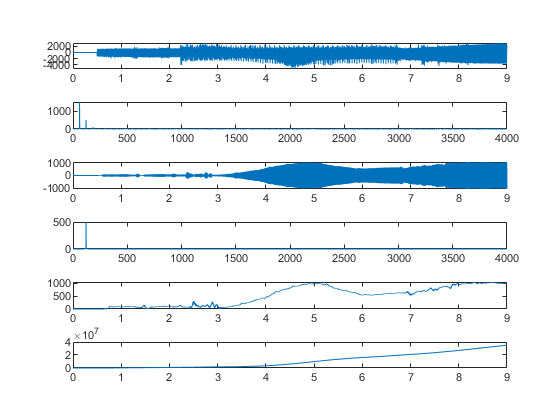




figure
subplot(6,1,1), plot(t(doff:nod),i(doff:nod))
subplot(6,1,2), plot(f(1:round(nod/2)),Imag(1:round(nod/2)))
subplot(6,1,3), plot(t(doff:nod),ifilt(doff:nod))
subplot(6,1,4), plot(f(1:round(nod/2)),Imagfilt(1:round(nod/2)))
subplot(6,1,5), plot(t(doff:nod),ienv(doff:nod))
subplot(6,1,6), plot(t(doff:nod),int_ienv(doff:nod))

## ------------------------- Plot Current vs. Time ------------------------%

Plot filtered version

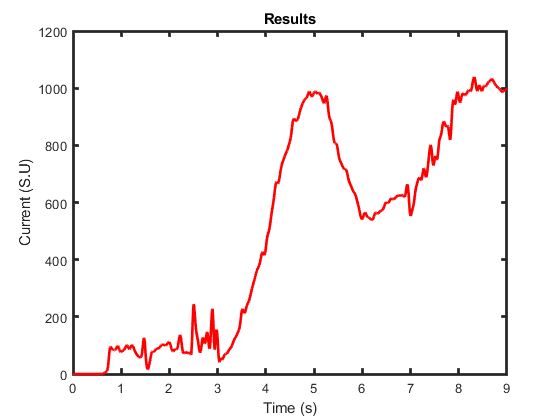

figure
plot(t(doff:nod-doff),ienv_filtered,'-r','linewidth',2);
xlabel('Time (s)');
ylabel('Current (S.U)');
title('Results');
set(gca,'linewidth',2);
hold on

## ----------------------------- Draw Baseline ----------------------------%

Choose two points (strating and finishing points of the baseline). The two points are found manually.

        fprintf(['\n Now select start point then end by positioning cursor,',...
            '\n   and selecting points with mouse button \n'])


 Now select start point then end by positioning cursor,
   and selecting points with mouse button 


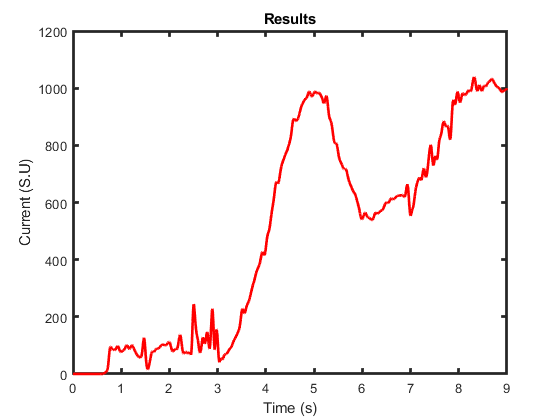

[x_start,y_start]=ginput(1); %this lets you graphically choose the start and end points
[x_end,y_end]=ginput(1);



num_of_points = 2;
Ax = linspace(x_start,x_end,num_of_points);         % Column 1: Voltage
Ay = linspace(y_start, y_end, num_of_points);       % Y-values (make them the same length)

## -------------- Difference between Response and Baseline ----------------%

% Area Between Two Curves
[~,x_start] = min(abs(x_start - t(doff:nod-doff)));
[~,x_end] = min(abs(x_end - t(doff:nod-doff)));

area_under_curve = trapz(t(x_start:x_end),ienv_filtered(x_start:x_end)); % Using trapezoid method to find the total area under curve (AC response)
area_under_baseline = trapz(Ax, Ay); % Using trapezoid method to find the total area under baseline
area_between_curves = area_under_curve - area_under_baseline; % Using trapezoid method to find the area between the curve (AC response)

## Plot shaded area

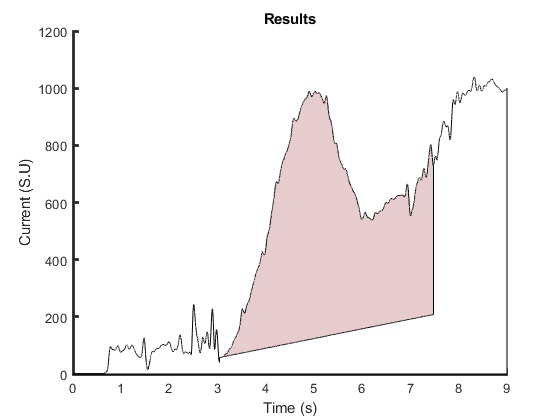

curve_1 = ienv_filtered;
curve_2 = curve_1;

curve_2(x_start:x_end) = linspace(y_start,y_end,x_end-x_start+1);
figure
hold on
area(t(doff:nod-doff),curve_1,'FaceColor',[0.9 0.8 0.8]); % Colour of the shaded area
area(t(doff:nod-doff),curve_2,'FaceColor','w');

xlabel('Time (s)');
ylabel('Current (S.U)');
title('Results');
set(gca,'linewidth',2);
hold on

Peak Height from the Baseline

[peak_height,~] = max(curve_1 - curve_2);   % First subtracting the baseline from the curve (AC response) and then finding the MAX (peak height).

## ----------------------------------END---------------------------------%%